# Práctica 1: Transformaciones, locomoción y sensado - Rodríguez, Maximiliano

## Transformaciones 2D y matrices afines

     La pose de un robot en el plano, con respecto a una terna global, se puede escribir como $\textbf{x} = (x, y, \theta)^T
$ donde $(x, y)^T


$es la posición del robot en el plano y $\theta$ es su orientación. La matriz de transformación homogénea que representa la pose $\textbf{x} = (x, y, \theta)^T
$ con respecto al origen de un sistema de coordenadas global está dado por:

$\textbf{T} = $$\left\lbrack \begin{array}{cc}
\mathit{\mathbf{R}}\left(\theta \right) & \mathit{\mathbf{t}}\\
0 & 1
\end{array}\right\rbrack$, $\textbf{R}(\theta) = $$\left\lbrack \begin{array}{cc}
\cos \left(\theta \right) & -\sin \left(\theta \right)\\
\sin \left(\theta \right) & \cos \left(\theta \right)
\end{array}\right\rbrack ,\;\mathbf{t}=\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack \ldotp$

### Transformando de terna del robot a terna global

    Supongamos entonces, que el robot estando en la pose $x_1 ={\left(x_1 ,y_1 ,\theta_1 \right)}^T$, detecta un obstáculo $p$ en la ubicación $\left(p_x ,\;p_y \right)$ con respecto a su propia terna de referencia. Si queremos expresar las coordenadas de p con respecto a la terna global, deberemos utilizar la transformación mencionada y luego multiplicar por el vector que queremos transformar.

$\mathbf{R}\left(\theta \right)=\left\lbrack \begin{array}{cc}
\cos \left(\theta_1 \right) & -\sin \left(\theta_1 \right)\\
\sin \left(\theta_1 \right) & \cos \left(\theta_1 \right)
\end{array}\right\rbrack$, $\mathbf{t}=\left\lbrack \begin{array}{c}
x_1 \\
y_1 
\end{array}\right\rbrack$ $\to \mathbf{T}=\left\lbrack \begin{array}{ccc}
\cos \left(\theta_1 \right) & -\sin \left(\theta_1 \right) & x_1 \\
\sin \left(\theta_1 \right) & \cos \left(\theta_1 \right) & y_1 \\
0 & 0 & 1
\end{array}\right\rbrack$,

entonces tenemos que:


$$p_{\textrm{global}} =\mathbf{T}\cdot p$$
 

$p_{\textrm{global}} =\;$$\left\lbrack \begin{array}{ccc}
\cos \left(\theta_1 \right) & -\sin \left(\theta_1 \right) & x_1 \\
\sin \left(\theta_1 \right) & \cos \left(\theta_1 \right) & y_1 \\
0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
p_x \\
p_y 
\end{array}\right\rbrack$,


$$p_{\mathrm{global}} =\left\lbrack \begin{array}{c}
\cos \left(\theta_1 \right)\cdot p_x -\sin \left(\theta_1 \right)\cdot p_y +x_1 \\
\sin \left(\theta_1 \right)\cdot p_x +\cos \left(\theta_1 \right)\cdot p_y +y_1 
\end{array}\right\rbrack$$


### Transformando de terna global a terna del robot

    Si las coordenadas del obstaculo se obtienen en base a la terna global, para calcular las coordenadas de dicho obstáculo en la terna del robot, solamente hay que multiplicar el vector por la inversa de la transformación $\mathbf{T}\ldotp$


$$p_{\textrm{robot}} ={\mathbf{T}}^{-1} \cdot p_{\textrm{global}} =\left\lbrack \begin{array}{cc}
{\mathbf{R}}^T  & -{\mathbf{R}}^T \cdot \mathbf{t}\\
0 & 1
\end{array}\right\rbrack \cdot p_{\textrm{global}} =\left\lbrack \begin{array}{ccc}
\cos \left(\theta_1 \right) & \sin \left(\theta_1 \right) & -\textrm{xcos}\left(\left.\theta_1 \right)-\textrm{ysin}\left(\theta_1 \right)\right)\\
-\sin \left(\theta_1 \right) & \cos \left(\theta_1 \right) & \textrm{xsin}\left(\theta_1 \right)-\textrm{ycos}\left(\theta_1 \right)\\
0 & 1 & 1
\end{array}\right\rbrack \cdot p_{\textrm{global}}$$


### Pose 2 respecto de pose 1

    Si el robot se moviera a una nueva posición ${\mathbf{x}}_2 =\left(x_2 ,y_2 ,\theta_2 \right)$, para representar la nueva pose con respecto a ${\mathbf{x}}_1$, deberemos hacer una transformación compuesta de la siguiente manera:


$${\mathbf{T}}_{12} ={\mathbf{T}}_{\textrm{global}\;}^1 \cdot {\mathbf{T}}_2^{\textrm{global}} ={\mathbf{T}}^{-1\;} \cdot {\mathbf{T}}_2 =\;$$

$$\left\lbrack \begin{array}{ccc}
\cos \left(\theta_1 \right) & \sin \left(\theta_1 \right) & -\textrm{xcos}\left(\left.\theta_1 \right)-\textrm{ysin}\left(\theta_1 \right)\right)\\
-\sin \left(\theta_1 \right) & \cos \left(\theta_1 \right) & \textrm{xsin}\left(\theta_1 \right)-\textrm{ycos}\left(\theta_1 \right)\\
0 & 1 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{ccc}
\cos \left(\theta_2 \right) & -\sin \left(\theta_2 \right) & x_2 \\
\sin \left(\theta_2 \right) & \cos \left(\theta_2 \right) & y_2 \\
0 & 0 & 1
\end{array}\right\rbrack$$



$$=\left\lbrack \begin{array}{ccc}
\cos \left(\theta_1 +\theta_2 \right) & \sin \left(\theta_1 -\theta_2 \right) & \cos \left(\theta_1 \right)\cdot \left(x_2 -x_1 \right)+\sin \left(\theta_1 \right)\cdot \left(y_2 -y_1 \right)\\
\sin \left(\theta_2 -\theta_1 \right) & \cos \left(\theta_1 -\theta_2 \right) & -\sin \left(\theta_1 \right)\cdot \left(x_2 +y_1 \right)+\cos \left(\theta_1 \right)\cdot \left(y_2 -x_1 \right)\\
0 & 0 & 1
\end{array}\right\rbrack$$


### Objeto P respecto a pose 2

    Para expresar a $p$ respecto de la pose 2 deberemos multiplicar el vector por la inversa de la transformada ${\mathbf{T}}_{12}$


$$p_2 ={\mathbf{T}}_{12}^{-1} \cdot p_1$$


## Sensado

    Un robot se encuentra en la pose $x=5m,\;y=-7m,\;\theta =-\frac{\pi \;}{4}$, según una terna global. Sobre el robot, hay montado un LIDAR en la posicion $x=0,2m,y=0m,\;\theta =\pi$ (con respecto a la terna del cuerpo del robot). El sensor produce una lectura que se encuentra en el archivo `laserscan.dat. `La primera medición se toma para el ángulo $\alpha =-\frac{\pi }{2}$ (según la terna del sensor) y la última se toma para el ángulo $\alpha =\frac{\pi }{2}$. El sensor tiene una apertura angular (FOV) de $\pi$ y todas las mediciones intermedias tienen una separación angular constante.

### Mediciones respecto al LIDAR

    Para graficar las mediciones respecto al LIDAR, primero se debe leer el archivo y crear un vector de ángulos según el barrido.

 scan = load('-ascii', 'laserscan.dat');
angulos = linspace(-pi/2, pi/2, size(scan,2));

    Luego, las mediciones están en coordenadas polares por lo que es necesario descomponerlas de la siguiente manera:

mediciones_x = scan .* cos(angulos);
mediciones_y = scan .* sin(angulos);

    Finalmente, se graficaron las mediciones:

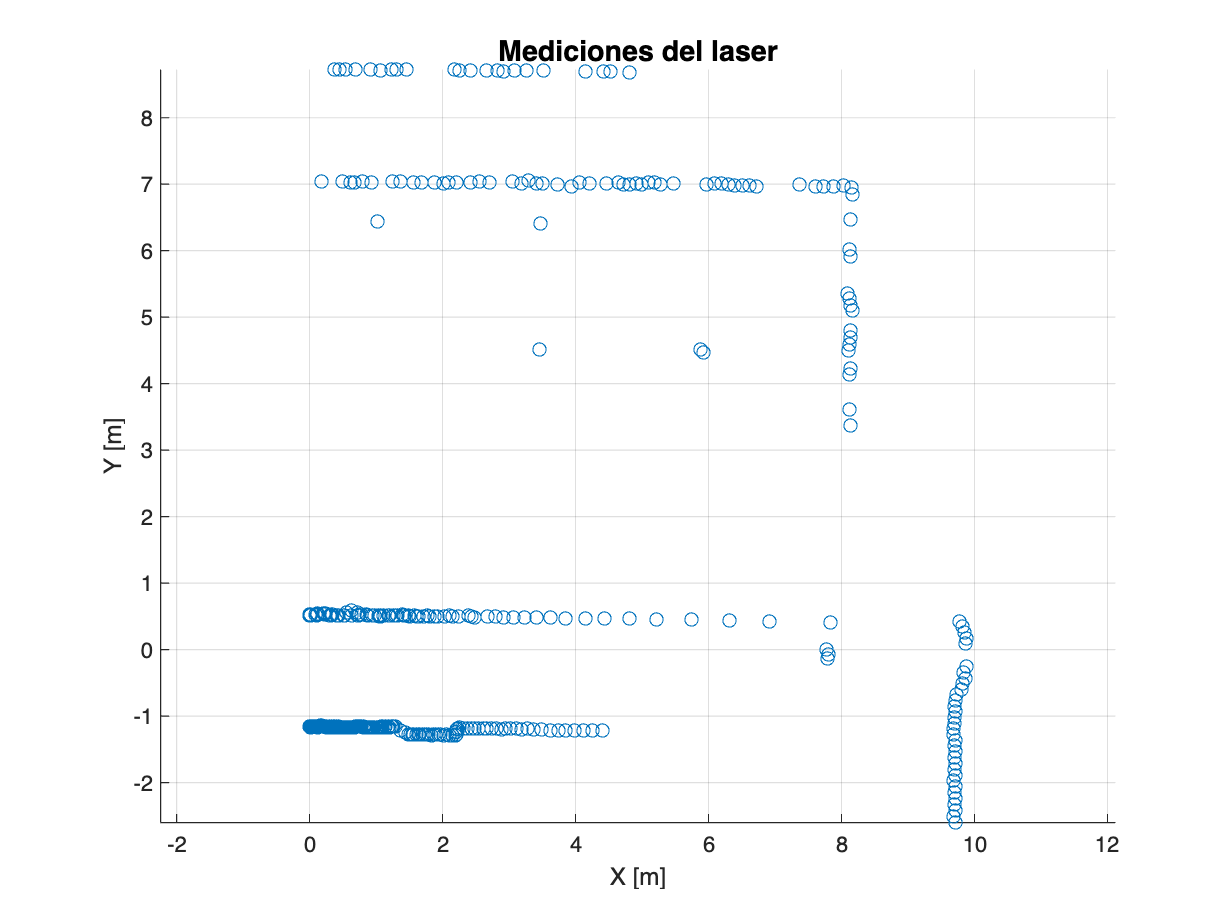

figure()
hold on
axis equal
grid on
xlabel('X [m]')
ylabel('Y [m]')
title('Mediciones del laser', 'FontSize', 13)
plot(mediciones_x, mediciones_y, "o");

Luego, se procedió a graficar la posición del robot:

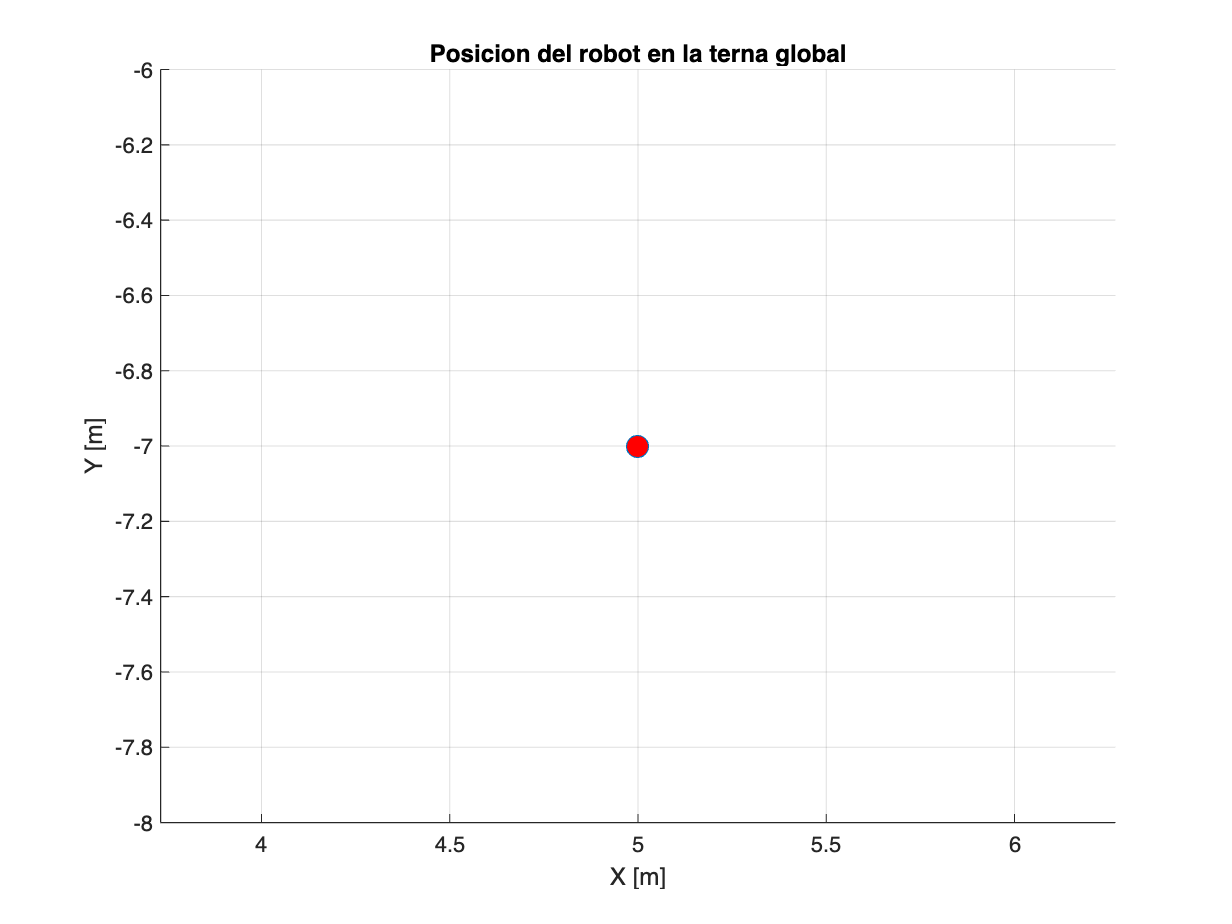

pose_robot = [5; -7];
figure();
grid on
title("Posicion del robot en la terna global");
hold on
axis equal
xlabel('X [m]')
ylabel('Y [m]')
plot(pose_robot(1), pose_robot(2), "o", 'MarkerSize', 10, 'MarkerFaceColor', 'r');

    Para poder graficar el LIDAR en la terna global, primero hay que calcular sus coordenadas en esa terna:


$${\mathbf{x}}_{\textrm{lidar}\;\textrm{global}} ={\mathbf{T}}_{\textrm{robot}}^{\textrm{global}} \cdot {\mathbf{T}}_{\textrm{lidar}}^{\textrm{robot}} \cdot {\mathbf{x}}_{\textrm{lidar}}$$


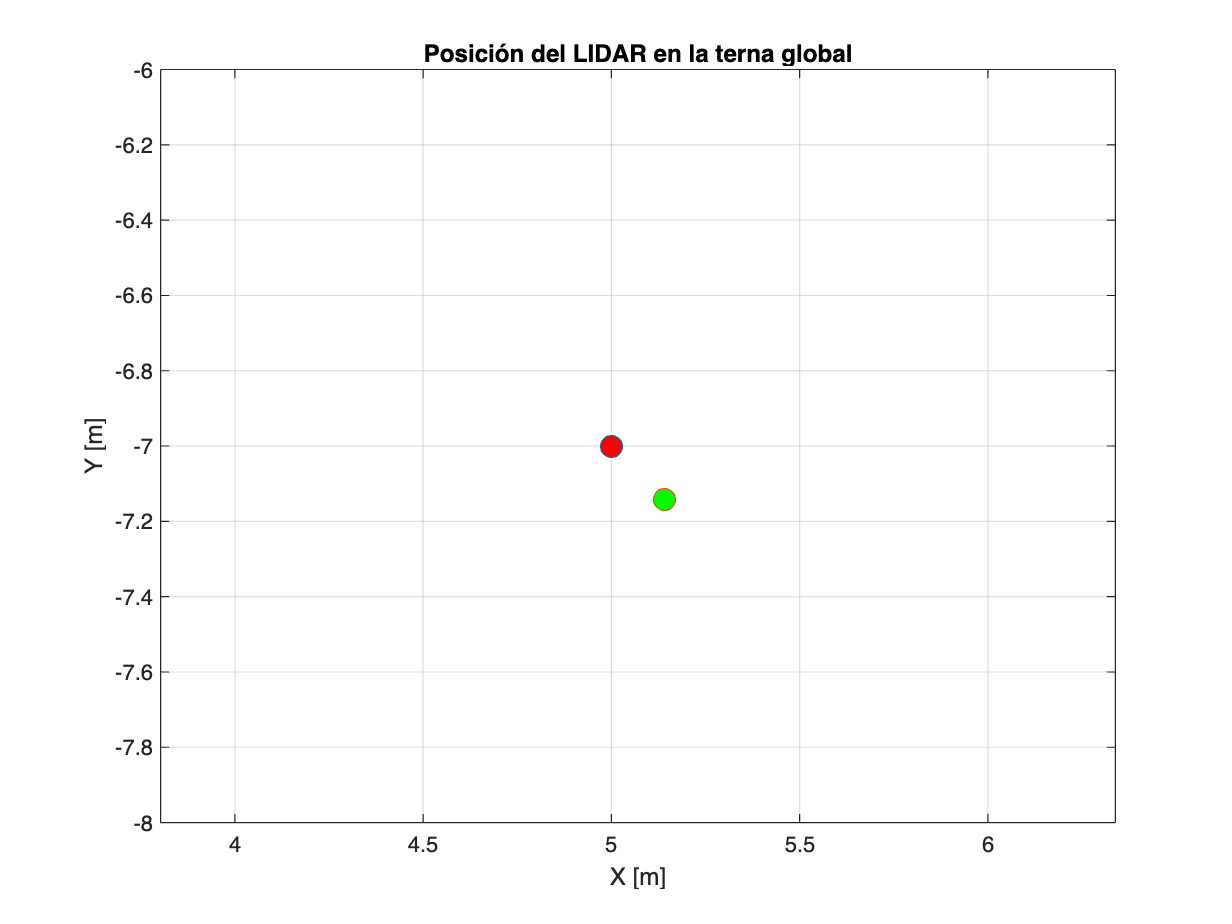

theta_robot = -pi/4;
theta_lidar = pi;

% Pose del robot en la global
T_robot_a_global = [cos(theta_robot), -sin(theta_robot), 5;
                    sin(theta_robot),  cos(theta_robot), -7;
                    0, 0, 1];

% Pose del LIDAR respecto al robot
T_lidar_a_robot = [cos(theta_lidar), -sin(theta_lidar), 0.2;
                   sin(theta_lidar),  cos(theta_lidar), 0;
                   0, 0, 1];

% Pose del LIDAR en la global
T_lidar_a_global = T_robot_a_global * T_lidar_a_robot;

% Origen del LIDAR en su propio sistema de referencia
posicion_lidar_homogeneo = [0; 0; 1];

% Posición del LIDAR en coordenadas globales
posicion_lidar_global = T_lidar_a_global * posicion_lidar_homogeneo;

% Graficar
figure();
plot(pose_robot(1), pose_robot(2), "o", 'MarkerSize', 10, 'MarkerFaceColor', 'r');
hold on
plot(posicion_lidar_global(1), posicion_lidar_global(2), "o", 'MarkerSize', 10, 'MarkerFaceColor', 'g')
xlabel("X [m]");
ylabel("Y [m]");
xlim([4 6]);
ylim([-8 -6]);
title("Posición del LIDAR en la terna global");
axis equal;
grid on;

Finalmente, para obtener las mediciones en la terna global, se tiene que aplicar las mismas transformaciones que para el lidar:

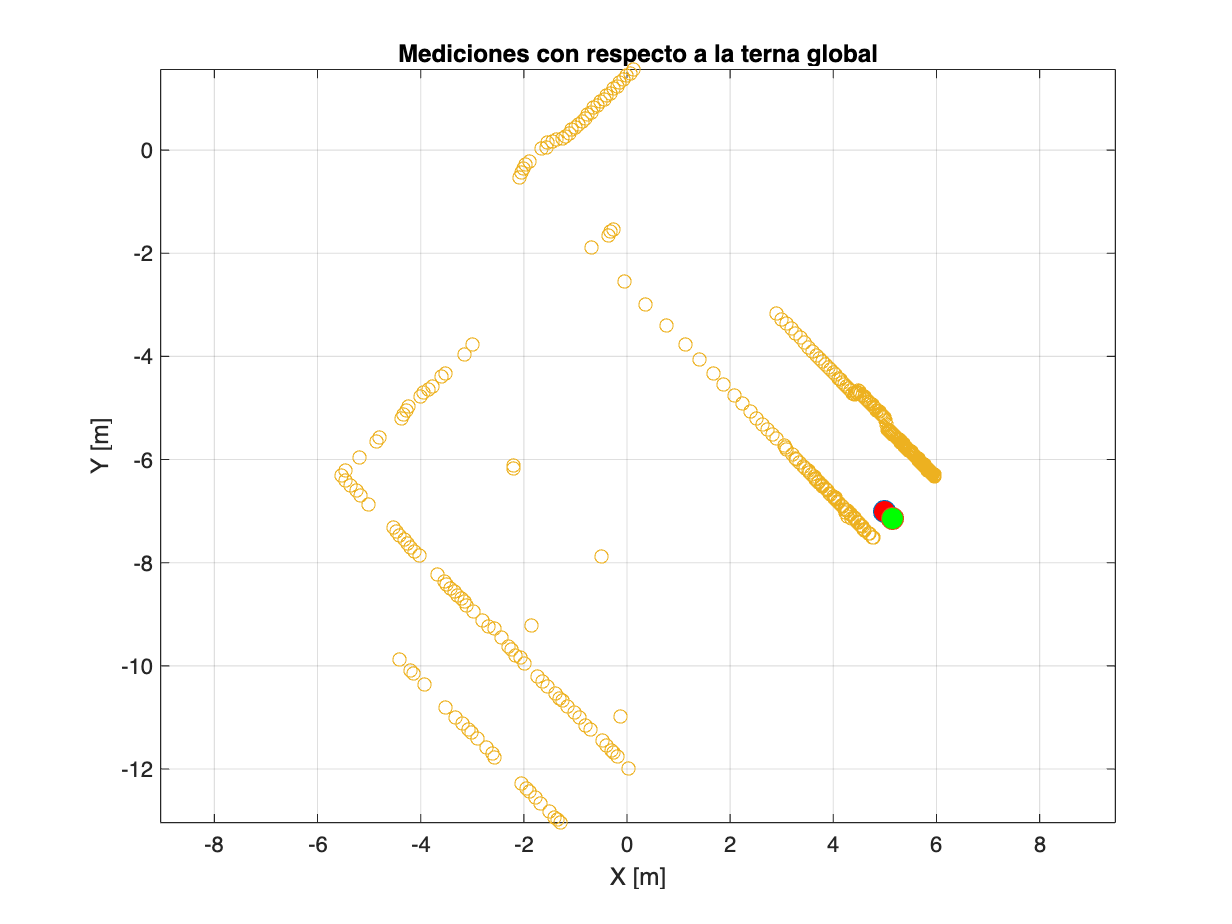

mediciones = [mediciones_x ; mediciones_y];
mediciones_homogeneas = [mediciones; ones(1, size(mediciones, 2))]; 

mediciones_terna_global = T_lidar_a_global * mediciones_homogeneas;

figure();
plot(pose_robot(1), pose_robot(2), "o", 'MarkerSize', 10, 'MarkerFaceColor', 'r');
hold on
plot(posicion_lidar_global(1), posicion_lidar_global(2), "o", 'MarkerSize', 10, 'MarkerFaceColor', 'g');
plot(mediciones_terna_global(1, :), mediciones_terna_global(2, :), "o");
xlabel("X [m]");
ylabel("Y [m]");
title("Mediciones con respecto a la terna global");
axis equal;
grid on

    Se puede interpretar las mediciones como las paredes de una habitación. Se observó que las paredes mas cercanas son las que tuvieron una mayor cantidad de muestras. Se determinó que las 4 mediciones entre x = [-2; 0] e y = [-11; -6] pueden haberse resultado a algunos objetos que estuviesen en esa localización.

## Accionamiento diferencial

    Anteriormente, vimos cómo calcular, para cada terna, las coordenadas del Robot. Ahora, para describir el movimiento del robot en base a las velocidades, deberemos hacer lo siguiente.

### Velocidad de traslación

    En primera instancia, se considera la contribución de las velocidades de giro de cada rueda a la velocidad de traslación del robot. El origen de coordenadas de la terna del robot se encuentra a la mitad de la distancia entre las ruedas. Si una rueda gira y la otra no aporta nada, el robot se mueve a la mitad de la velocidad. Por lo tanto, la velocidad lineal de cada rueda es:

$v_{\mathrm{r1}} =\frac{1}{2}\cdot r\cdot \dot{\phi_1 }$ ,   $v_{\textrm{r2}} =\frac{1}{2}\cdot r\cdot \dot{\phi_2 }$ .

Luego, la velocidad de traslación del robot es la suma de ambas:

$v_r =v_{\textrm{r1}} +v_{\textrm{r2}}$.

### Componente rotacional

    De la misma forma, se calculan los aportes de las ruedas a la componente rotacional de manera independiente y luego se las suma.

    Si la rueda 1 gira sola, el robot pivota alrededor de la rueda 2, resultando en una rotación en sentido antihorario. Por lo tanto:

$\omega_{1\;} =\frac{r\dot{\varphi_1 } }{l}$,

    En cambio, si la rueda 2 gira sola, el robot pivota alrededor de la rueda 1, resultando en una rotación en sentido horario:

   $\omega_2 =\frac{-r\dot{\varphi_2 } }{l}$,

    Luego, la velocidad angular del robot es la suma de ambas:


$$\omega_r =\omega_1 +\omega_2 \ldotp$$


### Cinemática 

    Por lo tanto, cuando las ruedas giran en la misma velocidad, el robot se desplaza linealmente en la dirección de la orientación. Por lo que las posiciones, en ese caso, se pueden calcular en la terna global como:

    
$$\begin{array}{l}
x\left(t\right)=\frac{1}{2}\int_0^t \left\lbrack v_{\textrm{r1}} \left(t\right)+v_{\textrm{r2}} \left(t\right)\right\rbrack \cdot \cos \left(\theta \left(t\right)\right)\cdot \;\textrm{dt}\;\;\;\;\;\;\;\;\;\;\;\;\;\\
y\left(t\right)=\frac{1}{2}\int_0^t \left\lbrack v_{\textrm{r1}} \left(t\right)+v_{\textrm{r2}} \left(t\right)\right\rbrack \cdot \textrm{sen}\left(\theta \left(t\right)\right)\cdot \;\textrm{dt}\\
\Theta \left(t\right)=\frac{1}{l}\int_0^t \left.{\left\lbrack v\right.}_{\textrm{r1}} \;\left(t\right)-v_{\textrm{r2}} \left(t\right)\right\rbrack \cdot \;\textrm{dt}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;
\end{array}$$


    Luego, cuando las ruedas giran a distintas velocidades, las trayectorias obtenidas son instantáneamente círculos. Para que se cumpla la condición de rodamiento, las ruedas deben girar en torno a un mismo punto, el centro de curvatura instantáneo (*ICC)*.

    Sabemos que:


$$\omega \left(R+\frac{l}{2}\right)=V_r \;\;\;\;\;y\;\;\;\;\;\;\;\omega \left(R-\frac{l}{2}\right)=V_l$$


    Por lo que:

$\omega =\frac{V_r -V_l }{l}$,


$$R=\frac{l}{2}\cdot \frac{V_r +V_l }{V_{r\;} -V_{l\;} }=\frac{v}{\omega }$$


    Para calcular el ICC:


$$\textrm{ICC}=\left\lbrack x-R\cdot \sin \left(\theta \right),\;\;y+R\cdot \cos \left(\theta \right)\right\rbrack$$


    Finalmente, el movimiento alrededor del ICC con velocidad angular $\omega$:

    $\left\lbrack \begin{array}{c}
x^{\prime } \\
y^{\prime } \\
\theta^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \left(\omega \delta t\right) & -\textrm{sen}\left(\omega \delta t\right) & 0\\
\textrm{sen}\left(\omega \delta t\right) & \cos \left(\omega \delta t\right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
x-{\textrm{ICC}}_x \\
y-{\textrm{ICC}}_y \\
\theta 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
{\textrm{ICC}}_x \\
{\textrm{ICC}}_y \\
\omega \delta t
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\textrm{ICC}}_x +\cos \left(\omega \delta t\right)\left(x-{\textrm{ICC}}_x \right)-\textrm{sen}\left(\omega \delta t\right)\left(y-{\textrm{ICC}}_y \right)\\
{\textrm{ICC}}_y +\sin \left(\omega \delta t\right)\left(x-{\textrm{ICC}}_x \right)+\cos \left(\omega \delta t\right)\left(y-{\textrm{ICC}}_y \right)\\
\theta +\omega \delta t
\end{array}\right\rbrack$ .

    Factorizando la expresion se llega a:

$\left\lbrack \begin{array}{c}
x^{\prime } \\
y^{\prime } \\
\theta^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x-R\cdot \sin \left(\theta \right)+R\cdot \sin \left(\theta +\omega \delta t\right)\\
y+R\cdot \cos \left(\theta \right)-R\cdot \cos \left(\theta +\omega \delta t\right)\\
\theta +\omega \delta t
\end{array}\right\rbrack$.

    Luego, se puede crear la función `diffdrive `para implementar la cinemática directa:

function [x_n, y_n, theta_n] = diffdrive(x, y, theta, v_l, v_r, t, l)
    v = (v_r + v_l) / 2;
    w = (v_r - v_l) / l;

    if abs(w) < 1e-6
        x_n = x + v * cos(theta) * t;
        y_n = y + v * sin(theta) * t;
    else
        R = v / w;
        x_n = x - R * sin(theta) + R * sin(theta + w * t);
        y_n = y + R * cos(theta) - R * cos(theta + w * t);
    end

    theta_aux = theta + w * t;
    theta_n = mod(theta_aux, 2*pi);
end   

    Luego, el robot ejecuta ciertas acciones:

pose = [0; 0; pi/4];
poses = pose;

acciones = [
    0.1  0.5  2;
    0.5  0.1  2;
    0.2  0.2  2;
    1.0  0.0  4;
    0.4  0.4  2;
    0.2 -0.2  2;
    0.5  0.5  2
];

l = 0.5;

for i = 1:size(acciones, 1)
    v_l = acciones(i, 1);
    v_r = acciones(i, 2);
    t   = acciones(i, 3);

    [x_n, y_n, theta_n] = diffdrive(pose(1), pose(2), pose(3), v_l, v_r, t, l);
    pose = [x_n; y_n; theta_n];
    poses = [poses pose];
end

Una vez computada las distintas poses, se procedió a graficarlas.

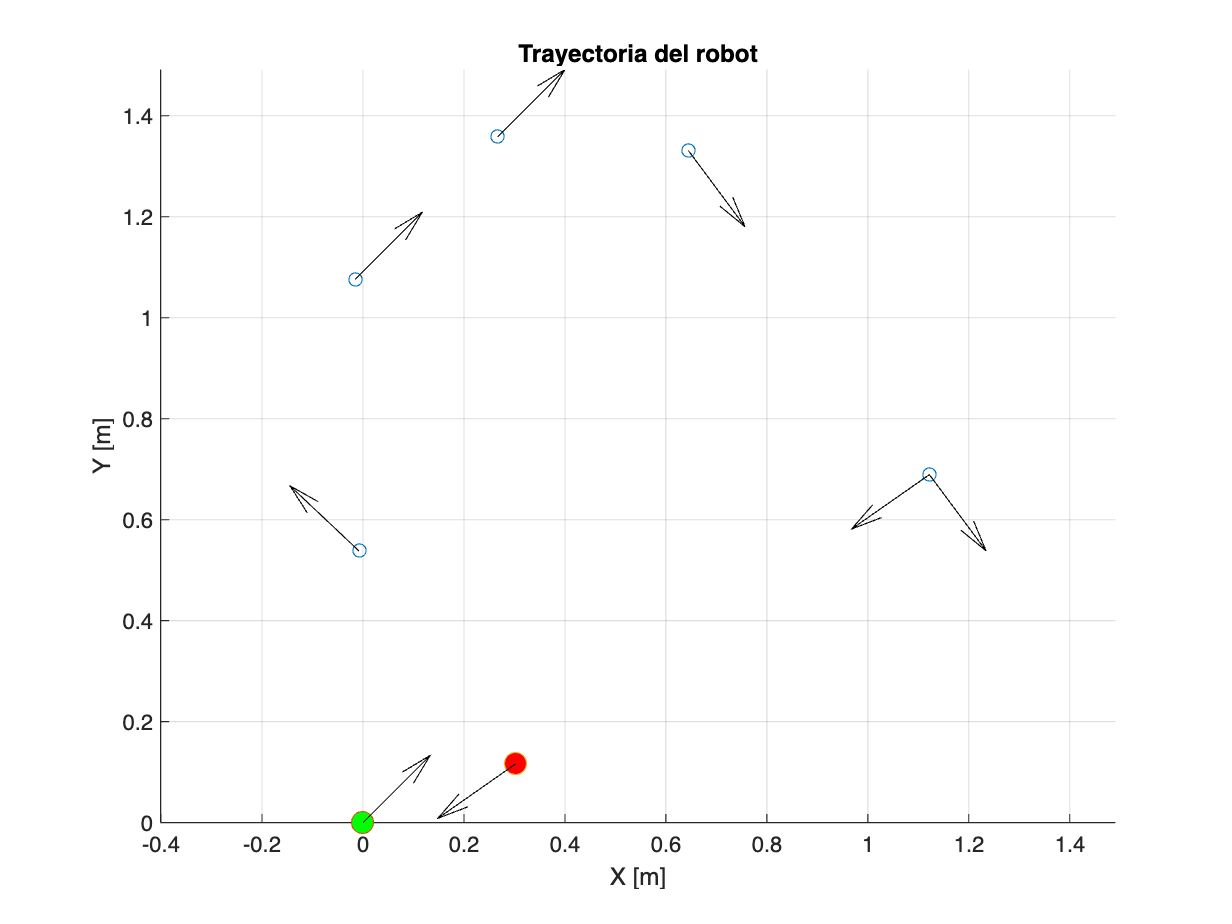

figure();
hold on
axis equal
grid on
xlabel('X [m]')
ylabel('Y [m]')
title('Trayectoria del robot')

% % Dibuja la trayectoria conectando los puntos
% plot(poses(1, :), poses(2, :), 'b.-');  % X vs Y

% Dibuja la trayectoria conectando los puntos
plot(poses(1, :), poses(2, :), 'o');  % X vs Y

% Dibuja la pose inicial
plot(poses(1, 1), poses(2, 1), "o", 'MarkerSize', 10, 'MarkerFaceColor', 'g');

% Dibuja la pose final
plot(poses(1, end), poses(2, end), "o", 'MarkerSize', 10, 'MarkerFaceColor', 'r');

quiver(poses(1, :), poses(2, :), cos(poses(3, :)), sin(poses(3, :)), 0.3, 'k');

Para estimar la trayectoria, en vez de realizar el `diffdrive `para el $\Delta t$ otorgado, se puede usar la función con distintos pasos para cada intervalo entre acciones.

function tray = simular_movimiento(x, y, theta, v_l, v_r, t_total, l, dt)
    pasos = floor(t_total / dt);
    tray = zeros(3, pasos + 1);
    tray(:,1) = [x; y; theta];

    for i = 1:pasos
        [x, y, theta] = diffdrive(x, y, theta, v_l, v_r, dt, l);
        tray(:, i+1) = [x; y; theta];
    end
end

    Luego, se realizan los mismos pasos que para el punto anterior, ademas de definir el delta t.

pose = [0; 0; pi/4];
poses_anim = pose; 

acciones = [
    0.1  0.5  2;
    0.5  0.1  2;
    0.2  0.2  2;
    1.0  0.0  4;
    0.4  0.4  2;
    0.2 -0.2  2;
    0.5  0.5  2
];  
dt = 0.05;

    Se agregan gráficos interactivos para el .m o el .mlx.

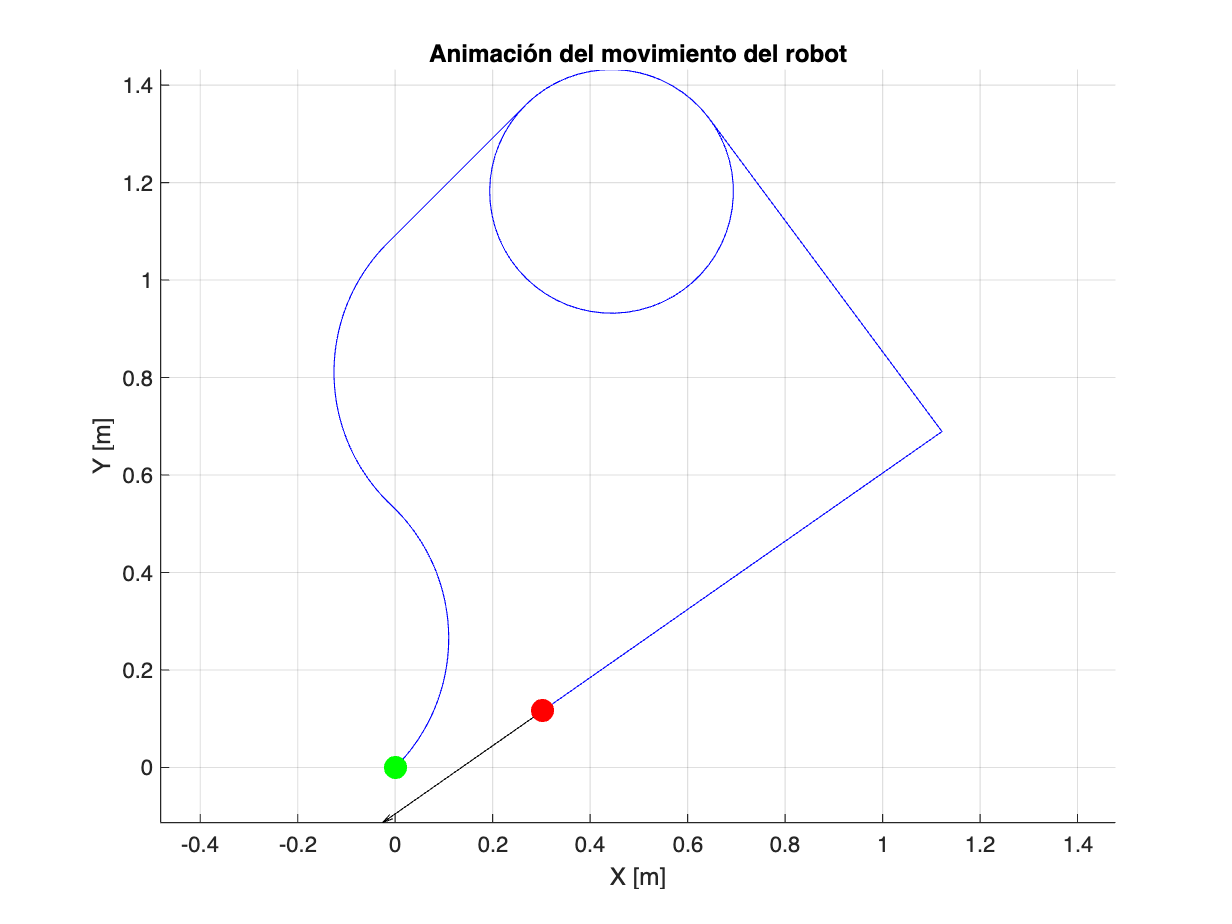

figure();
axis equal
grid on
xlabel('X [m]')
ylabel('Y [m]')
title('Animación del movimiento del robot')
hold on

h_trayectoria = plot(nan, nan, 'b-');        % línea de trayectoria
h_robot = plot(pose(1), pose(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');  
h_orient = quiver(pose(1), pose(2), cos(pose(3)), sin(pose(3)), 0.4, 'k');        

for i = 1:size(acciones, 1)
    v_l = acciones(i, 1);
    v_r = acciones(i, 2);
    t_total = acciones(i, 3);

    pasos = round(t_total / dt);

    for j = 1:pasos
        [x_n, y_n, theta_n] = diffdrive(pose(1), pose(2), pose(3), v_l, v_r, dt, l);
        pose = [x_n; y_n; theta_n];
        poses_anim = [poses_anim pose];

        % actualizar gráficos
        set(h_trayectoria, 'XData', poses_anim(1,:), 'YData', poses_anim(2,:));
        set(h_robot, 'XData', pose(1), 'YData', pose(2));
        set(h_orient, 'XData', pose(1), 'YData', pose(2), ...
                      'UData', cos(pose(3)), 'VData', sin(pose(3)));

        pause(dt * 0.5);  
    end
end

plot(poses_anim(1,1), poses_anim(2,1), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');  % inicio
plot(poses_anim(1,end), poses_anim(2,end), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');  % final